# `1D FEM for linear and quadratic Element`

This section clears the workspace and clears the command window of matlab so that command space is clean and the all the pre-existing variables are deleted. (Fresh Start!!!)

clear
clc

## Input Information

#### Geometry characteretics and Material Properties

This section takes in all the properties of bar such as length of bar, cross section area, Elastic modulus and also number of elements the user prefers.

geo_prompt = {'Enter length of bar (in meters)','Enter the cross section area (in sqm)','Enter the Youngs Modulus (in GPa)','Number of elements'};
dlgtitle = 'Input Geometry and Material properties';
data1 = inputdlg(geo_prompt,dlgtitle);
L = str2double(data1{1});
CSA = str2double(data1{2});
E = str2double(data1{3});
num_elem = str2double(data1{4});

#### Element, Mesh and Descretization 

As the element type is not fixed, this is the code to ask user for type of descritization and also displays the mesh according to the given inputs (number of elements and length of bar)

data2 = questdlg('Type of element??','Element descretization','Linear','Quadratic','Linear');
fem_descr = data2;
le = L/num_elem;  % length of each element
X = linspace(0,L,num_elem+1);
Y = [0 1];
Z = zeros([2 num_elem+1]);
[X ,Y] = meshgrid(X,Y);
mesh(X,Y,Z,'EdgeColor',[0 0 0],'MarkerSize',5)
title('Mesh')
view(2)
daspect([0.1*L 1 1])
clear X Y Z

## Boundary Conditions

Input for defining the body force (can be constant or distribution)

Traction boundary condition (Natural boundary condition)


$${\left\lbrack \frac{\textrm{du}}{\textrm{dx}}\right\rbrack }_{x=L} =0\;$$


Displacement boundary condition (Essential boundary condition) are taken as input in this section

Type of force is also taken as input just inorder to make less computation if there is no distribution force or no point force.

This can also be tested by putting distribution as '0' in mixed input and point as '0' which means point load only and distributive loads only respectively.

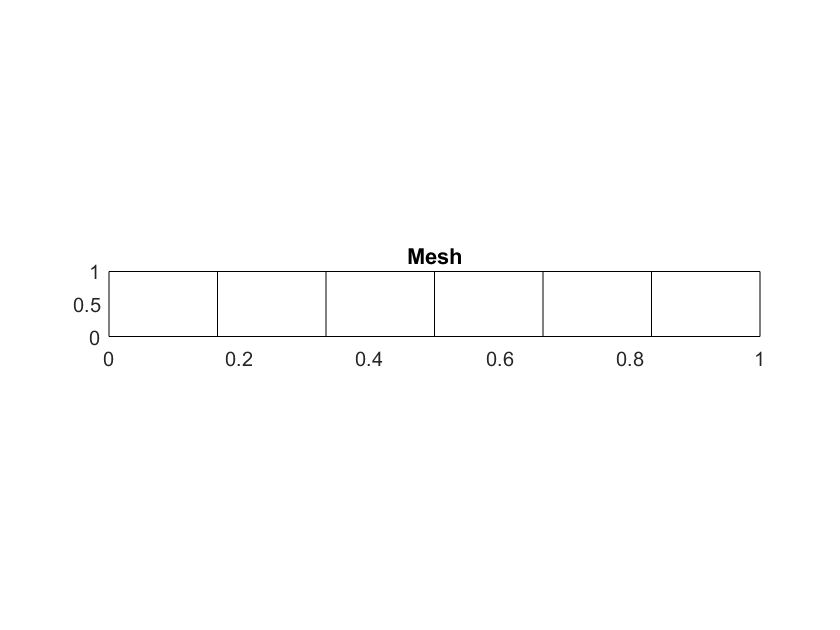

%----------------
data4 = questdlg('Fixed at ??','Displacement boundary condition','One end','Both ends','One end');

%----------------
% PS1_prompt = {'Type of force ("Distribution"/"Point" Loads/"Composite"'};
% dlgtitle = 'Problem Specification';   
% data3 = inputdlg(PS1_prompt,dlgtitle);
% typ_for = data3{1};
data3 = questdlg('Type of force?? ("Distribution only" or "Point only" or "Mixed Loads"','Problem Specification','Distribution','Point','Mixed','Point');
typ_for = data3;
%----------------
Distribution = "Distribution";
Point = "Point";
Composite = "Mixed";
if contains(typ_for,Distribution)
    PS3_prompt = {'Enter force distribution as function of x (small) Eg:2*(x^2)+x+5'};
    dlgtitle = 'Loads/Body Force Conditions';
    data5 = inputdlg(PS3_prompt,dlgtitle);
    b = str2sym(data5{1});
    po_lbc = 0;
    val_lbc = 0;
elseif contains(typ_for,Point)
    PS3_prompt = {'Enter points at which load boundary conditions are to be specified (Eg: If you are going to apply at x=3 & x=5 please enter 3,5','Enter the respective values of loads(in same order)'};
    dlgtitle = 'Loads/Body Force Conditions';
    data5 = inputdlg(PS3_prompt,dlgtitle);
    po_lbc = str2num(data5{1});
    val_lbc = str2num(data5{2});
    b = 0;
elseif contains(typ_for,Composite)
    PS3_prompt = {'Enter force distribution as function of x (small) Eg:2*(x^2)+x+5'};
    dlgtitle = 'Loads/Body Force Conditions';
    data5 = inputdlg(PS3_prompt,dlgtitle);
    b = str2sym(data5{1});
    PS4_prompt = {'Enter points at which load boundary conditions are to be specified (Eg: If you are going to apply at x=3 & x=5 please enter 3,5','Enter the respective values of loads(in same order)'};
    dlgtitle = 'Loads/Body Force Conditions';
    data6 = inputdlg(PS4_prompt,dlgtitle);
    po_lbc = str2num(data6{1});
    val_lbc = str2num(data6{2});    
end
clear PS3_prompt PS1_prompt PS2_prompt dlgtitle data1 data2 data3 data5 data6
linear = "Linear";
quadratic = "Quadratic";

## Function Call

if contains(fem_descr,linear)
    [sigma u] = linear_fem(L,num_elem,CSA,E,b,typ_for,po_lbc,val_lbc,data4);
elseif contains(fem_descr,quadratic)
    [sigma u] = quadratic_fem(L,num_elem,CSA,E,b,typ_for,po_lbc,val_lbc,data4);    
end

K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    14     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    28   -16     2     0     0     0     0     0     0     0     0
     0     0   -16    32   -16     0     0     0     0     0     0     0     0
     0     0     2   -16    14     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    28   -16     2     0     0     0     0     0     0     0     0
     0     0   -16    32   -16     0     0     0     0     0     0     0     0
     0     0     2   -16    28   -16     2     0     0     0     0     0     0
     0     0     0     0   -16    32   -16     0     0     0     0     0     0
     0     0     0     0     2   -16    14     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    28   -16     2     0     0     0     0     0     0     0     0
     0     0   -16    32   -16     0     0     0     0     0     0     0     0
     0     0     2   -16    28   -16     2     0     0     0     0     0     0
     0     0     0     0   -16    32   -16     0     0     0     0     0     0
     0     0     0     0     2   -16    28   -16     2     0     0     0     0
     0     0     0     0     0     0   -16    32   -16     0     0     0     0
     0     0     0     0     0     0     2   -16    14     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    28   -16     2     0     0     0     0     0     0     0     0
     0     0   -16    32   -16     0     0     0     0     0     0     0     0
     0     0     2   -16    28   -16     2     0     0     0     0     0     0
     0     0     0     0   -16    32   -16     0     0     0     0     0     0
     0     0     0     0     2   -16    28   -16     2     0     0     0     0
     0     0     0     0     0     0   -16    32   -16     0     0     0     0
     0     0     0     0     0     0     2   -16    28   -16     2     0     0
     0     0     0     0     0     0     0     0   -16    32   -16     0     0


K_net =     14   -16     2     0     0     0     0     0     0     0     0     0     0
   -16    32   -16     0     0     0     0     0     0     0     0     0     0
     2   -16    28   -16     2     0     0     0     0     0     0     0     0
     0     0   -16    32   -16     0     0     0     0     0     0     0     0
     0     0     2   -16    28   -16     2     0     0     0     0     0     0
     0     0     0     0   -16    32   -16     0     0     0     0     0     0
     0     0     0     0     2   -16    28   -16     2     0     0     0     0
     0     0     0     0     0     0   -16    32   -16     0     0     0     0
     0     0     0     0     0     0     2   -16    28   -16     2     0     0
     0     0     0     0     0     0     0     0   -16    32   -16     0     0


one = "One"

d =          0
    0.0831
    0.1651
    0.2448
    0.3210
    0.3926
    0.4583
    0.5172
    0.5679
    0.6094


## Convergence

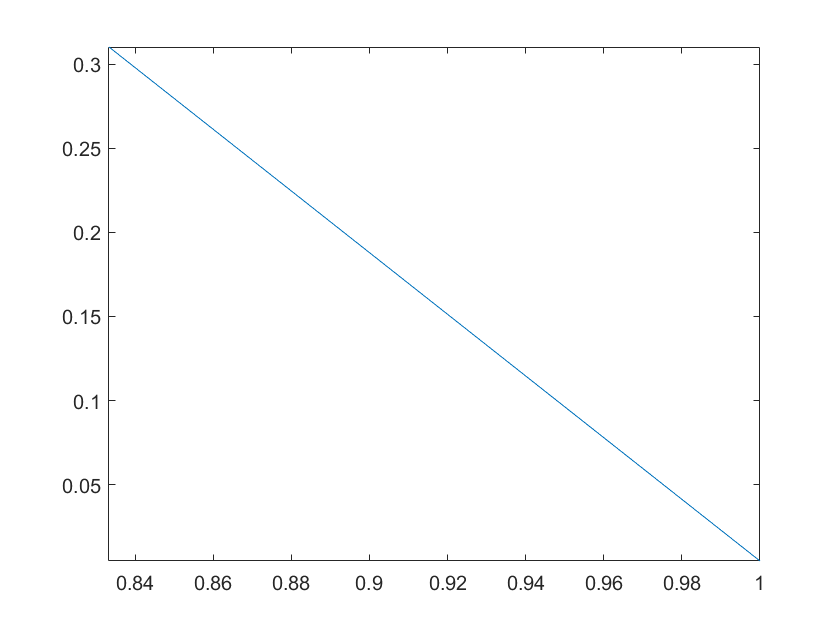

data8 = questdlg('Do you want check convergence plot??  Note: May take more time','Convergence','Yes','No','Yes');

if contains(data8,"Yes")
    if contains(fem_descr,linear)
        for hg = num_elem-10 : num_elem+10
            [sigma u] = linear_fem(L,hg,CSA,E,b,typ_for,po_lbc,val_lbc,data4);
            S{hg-num_elem+11} = max(cell2mat(sigma));
        end
        S = cell2mat(S);
        plot(S)   
    end
    if contains(fem_descr,quadratic)
%         for hg = num_elem-10 : num_elem+10
%                 sigma = quadratic_fem(L,hg,CSA,E,b,typ_for,po_lbc,val_lbc,data4);
%                 x1 = 0;
%                 Sm_elem = zeros([1 num_elem])
%                 for i = 1:num_elem
%                     x2 = x1+L/num_elem;
%                     if diff(sigma{i})>1
%                         Sm_elem[i] = double(subs(sigma{i},x2));
%                     else
%                         Sm_elem[i] = double(subs(sigma{i},x1));
%                     end
%                     x1 = x1+L/num_elem;
%                 end
%                 S = cell2mat(S);
%         end
    end
     
else 
end

## Convergence rate 

%% Only for Question 1
% % Find L2 error
% syms x
% an1 = x-(x^3/3);
% an2 = (2/3)*(x-(x^4/4));
% sum = 0;
% x1 = 0;
% for i = 1:num_elem
%     x2 = x1 + (L/num_elem);
%     L2{i} = ((int((an1-u{i})^2,x,[x1 x2]))^0.5)/((int((an1)^2,x,[x1 x2]))^0.5);    
%     sum = sum + L2{i}^2
%     x1 = x1 + (L/num_elem);
% end

$$sum = \frac{1}{3229752}$$

$$sum = \frac{130112}{365899815237}$$

$$sum = \frac{830620307549}{2221531944092646856}$$

$$sum = \frac{1257303440031051136}{3269878144648334127382683}$$

$$sum = \frac{55736118678763979736277385}{142118661482800231805087513106072}$$

$$sum = \frac{15016858650949383292477920112192}{37661581489992649111903670848642473319}$$

% RMS_Le = (sum/num_elem)^0.5;

# LINEAR FUNCTION DEFINITION

## Shape and Gather Matrices

#### Nodal mode shape matrix

Shape matrix is defined in this section for all the elements using **for** loop

function [sigma u] = linear_fem(L,num_elem,CSA,E,b,typ_for,po_lbc,val_lbc,data4)
    syms x;
    x1 = 0;
    le = L/num_elem;
    for i = 1:num_elem
        x2 = x1+le;
        N{i} = [(x2-x)/(le), (x-x1)/(le)];
        x1 = x1+le;
    end
%     elseif contains(fem_descr,quadratic) %% develop N matrix
%     for i = 1:num_elem
%         x2 = x1+le;
%         N{i} = [((x-x2)*(x-x3))/((x1-x2)*(x1-x3)) , ((x-x1)*(x-x3))/((x2-x1)*(x2-x3)) , ((x-x1)*(x-x2))/((x3-x1)*(x3-x2))];
%     end

#### Gather/Scatter matrices (Linear)

Gather matrices are deifned in this section for each element similar to shape matrices

    for gt = 1:num_elem
        LM{gt} = zeros([num_elem+1 2]);
        LM{gt}(gt,1) = 1;
        LM{gt}(gt,2) = 0;
        LM{gt}(gt+1,1) = 0;
        LM{gt}(gt+1,2) = 1;
    end
        % L matrix - LM

## Calculations (Linear)

#### B = dN/dx

Simple differentiation of shape matrix which is done with help of pre-defined '***diff'*** function

    B = diff(N{1},x);

#### Individual stiffness matrices and Net Stiffness matrix (Linear)

Stiffness matrices for each element is defined in this section using the formula 


$$k_i^e =\int_{\textrm{x1}}^{\textrm{x2}} B_i^{e\;T} *\textrm{CSA}*E*B_i^{e\;} *\textrm{dx}$$


In the code below note that the k matrices for each element is of size (number of nodes x number of nodes) which means all the remaining terms are defined as zero. This helps in final addition of all k matrices to write global stiffness matrix K.

    x1 = 0;
    K_net = zeros([num_elem+1 num_elem+1]);
    for j = 1:num_elem
        x2 = x1+le;
        Ke{j} = zeros([num_elem+1 num_elem+1]);
        temp = double(int(transpose(B)*CSA*E*B,x,[x1,x2]));
        Ke{j}(j,j) = temp(1);
        Ke{j}(j+1,j) = temp(2);
        Ke{j}(j,j+1) = temp(3);
        Ke{j}(j+1,j+1) = temp(4);
        K_net = K_net+Ke{j};
        x1 = x1+le;
    end    

## Forces (Linear)

#### Body Force (Linear)

Calculate the body force on each element using the formula


$$f_{b\;i}^e =\int_{\textrm{x1}}^{\textrm{x2}} N_i^{e\;T} *b*\textrm{dx}$$


    Distribution = "Distribution";
    Composite = "Mixed";
    if contains(typ_for,Distribution) || contains(typ_for,Composite)
        x1 = 0;
        for m = 1:num_elem
            x2 = x1+le;
            fb{m} = double(int(transpose(N{m})*b,x,[x1,x2]));
            x1 = x1+le;
        end

Net body force which can be calculated using gather matrices,


$$F_b =\sum_{i=1}^{\textrm{num}\;\textrm{of}\;\textrm{elements}} L_i *$$

$$f_{b\;i}^e$$


        % Fb = L1*fb{1}+L2*Fb{2}.....
        Fb = zeros([num_elem+1 1]);
        for e = 1: num_elem
            Fb = Fb+LM{e}*fb{e};
        end
    else
        Fb = zeros([num_elem+1 1]);
    end
    clear m e

#### Traction boundary force (External Force) (Linear)

Calculate the traction/point load matrix on each element.


$$f_{t\;i}^e ={\left\lbrack N_i^{e\;T} *\tau *\textrm{CSA}\right\rbrack }_{x=\textrm{location}\;\textrm{of}\;\textrm{traction}}$$



$$f_{t\;i}^e ={\left\lbrack N_i^{e\;T} *P\right\rbrack }_{x=\textrm{location}\;\textrm{of}\;\textrm{point}\;\textrm{force}}$$


    Point = "Point";
    Composite = "Mixed";
    if contains(typ_for,Point) || contains(typ_for,Composite)
        x1 = 0;
        for m = 1:num_elem
            x2 = x1+le;
            for i = 1:max(size(po_lbc))
                if x1<po_lbc(i) && (abs(x2-po_lbc(i))<10^-6 || x2>=po_lbc(i))
                    ft{m} = double(subs((transpose(N{m})*val_lbc(i)),po_lbc(i)));
                    break
                else 
                    ft{m} = zeros([2 1]);  
    % since each element has two nodes (linear)
                end
            end
            x1 = x1+le;
        end

Net point/traction load matrix


$$F_t =\sum_{i=1}^{\textrm{num}\;\textrm{of}\;\textrm{elements}} L_i *$$

$$f_{t\;i}^e$$


        % Ft = L1*fb{1}+L2*Fb{2}.....
        Ft = zeros([num_elem+1 1]);
        for e = 1: num_elem
            Ft = Ft+LM{e}*ft{e};
        end
    else
        Ft = zeros([num_elem+1 1]);
    end
    clear m e

## Solving residual/governing equations (Linear)

${\mathit{\mathbf{F}}}_{\textrm{net}}$** =  **${\mathit{\mathbf{F}}}_b +$ ${\mathit{\mathbf{F}}}_t$


$${\mathit{\mathbf{K}}}_{\textrm{net}} *\mathit{\mathbf{d}}\;-{\mathit{\mathbf{F}}}_{\textrm{net}} =\mathit{\mathbf{r}}$$


${\mathit{\mathbf{K}}}_{\textrm{net}}$ - Global stiffness matrix

$\mathit{\mathbf{d}}$ - Node displacement matrix

${\mathit{\mathbf{F}}}_{\textrm{net}}$ - Net force matrix

$\mathit{\mathbf{r}}$ - Reaction force matrix

where rm is reaction force matrix

    one = "One";
    if contains(data4,one)
        A1 = K_net(2:end,2:end);
        F_net = Fb+Ft;
        B1 = F_net(2:end,:);
        d = linsolve(A1,B1);
        R = K_net*[0; d] - F_net;
        r = R(1);
        d = [0;d];
    else     
        A1 = K_net(2:end-1,2:end-1);
        F_net = Fb+Ft;
        B1 = F_net(2:end-1,:);
        d = linsolve(A1,B1);
        R = K_net*[0; d;0] - F_net;
        r = R(1);
        d = [0;d;0];
    end

Solving we get nodal displacements i.e., **d **matrix and then interpolating using shape matrices we get the displacement as function of position in each element.

**Note**: Check for continuity of displacement expressions at node points.

## Post Processing

### Plotting the expressions (Linear)

    syms x
    x1 = 0;
    for i = 1:num_elem
        x2 = x1 + le;
        u{i} = d(i)*((x2-x)/(le))+d(i+1)*((x-x1)/(le));
        fplot(u{i},[x1 x2])
        hold on
        x1 = x1 + le;
    end
    XA = [0 L];
    YA = [0 max(d)/50];  % Just to scale height of colour plot
    imagesc(XA,YA,transpose(d),"AlphaData",0.7)
    colormap("jet")
    axis([0 L 0 inf])
    title('Displacement variation (Linear)')
    xlabel('Position')
    ylabel('Displacement')
    colorbar
    hold off    
    x1 = 0;
    figure
    for i = 1:num_elem
        x2 = x1 + le;
        epsilon{i} = double(diff(u{i},x));
        sigma{i} = epsilon{i} * E;        
        fplot(sigma{i},[x1 x2])
        hold on
        x1 = x1 + le;
    end
    title('Stress Distribution (Linear)')
    xlabel('Position')
    ylabel('Displacement')
    hold off
end

# QUADRATIC FUNCTION DEFINITION

#### Shape matrices (Quadratic)

function [sigma u] = quadratic_fem(L,num_elem,CSA,E,b,typ_for,po_lbc,val_lbc,data4) %% develop N matrix
    syms x;
    x1 = 0;
    le = L/num_elem;
    for i = 1:num_elem
        x2 = x1+le/2;
        x3 = x1+le;
        N{i} = [((x-x2)*(x-x3))/((x1-x2)*(x1-x3)) , ((x-x1)*(x-x3))/((x2-x1)*(x2-x3)) , ((x-x1)*(x-x2))/((x3-x1)*(x3-x2))];
        x1 = x1+le;
    end    

#### Gather/Scatter matrices (Quadratic)

    for gt = 1:num_elem
        LM{gt} = zeros([2*num_elem+1 3]);
        LM{gt}(2*gt-1,1) = 1;
        LM{gt}(2*gt-1,2) = 0;
        LM{gt}(2*gt-1,3) = 0;
        LM{gt}(2*gt,1) = 0;
        LM{gt}(2*gt,2) = 1;
        LM{gt}(2*gt,3) = 0;
        LM{gt}(2*gt+1,1) = 0;
        LM{gt}(2*gt+1,2) = 0;
        LM{gt}(2*gt+1,3) = 1;
    end
    % L matrix - LM

## Calculations

#### B = dN/dx (Quadratic)

    for i = 1:num_elem
        B{i} = diff(N{i},x);
    end

#### Individual stiffness matrices and Net Stiffness matrix (Quadratic)

    x1 = 0;
    K_net = zeros([2*num_elem+1 2*num_elem+1]);
    for j = 1:num_elem
        x2 = x1+le/2;
        x3 = x1+le;        
        ke{j} = double(int(transpose(B{j})*CSA*E*B{j},x,[x1,x3]));
        K_net = K_net + (LM{j}*ke{j}*transpose(LM{j}))
        x1 = x1+le;
    end

## Forces

#### Body Force (Quadratic)

Calculate the body force on each element

    Distribution = "Distribution";
    Composite = "Mixed";
    if contains(typ_for,Distribution) || contains(typ_for,Composite)
        x1 = 0;
        for m = 1:num_elem
            x3 = x1+le;
            x2 = x1+le/2;
            fb{m} = double(int(transpose(N{m})*b,x,[x1,x3]));
            x1 = x1+le;
        end

Net body force

        % Fb = L1*fb{1}+L2*Fb{2}.....
        Fb = zeros([2*num_elem+1 1]);
        for e = 1: num_elem
            Fb = Fb+LM{e}*fb{e};
        end
    else
        Fb = zeros([2*num_elem+1 1]);        
    end
    Fb;
    clear m e

#### Traction boundary force (External Force) (Quadratic)

Calculate the traction/point load matrix on each element

    Point = "Point";
    Composite = "Mixed";
    if contains(typ_for,Point) || contains(typ_for,Composite)
        x1 = 0;
        for m = 1:num_elem
            x3 = x1+le;
            for i = 1:max(size(po_lbc))                
                if x1<po_lbc(i) && (logical(abs(x3-po_lbc(i))<10^-6) || po_lbc(i)<=x3)
                    ft{m} = double(subs((transpose(N{m})*val_lbc(i)),po_lbc(i)));
                    break;
                else
                    ft{m} = zeros([3 1]);  
                end   % since each element has two nodes (linear)
            end
            x1 = x1+le;
            ft
        end

Net point/traction load matrix

        % Ft = L1*fb{1}+L2*Fb{2}.....
        Ft = zeros([2*num_elem+1 1]);
        for e = 1: num_elem
            Ft = Ft+LM{e}*ft{e};
        end
    else
        Ft = zeros([2*num_elem+1 1]);
    end
    clear m e

## Solving residual/governing equations (Quadratic)

K_net*d - Fb = rm

where rm is reaction force matrix

    one = "One"
    if contains(data4,one)
        A1 = K_net(2:end,2:end);
        F_net = Fb+Ft;
        B1 = F_net(2:end,:);
        d = linsolve(A1,B1);
        R = K_net*[0; d] - F_net;
        r = R(1);
        d = [0;d];
    else     
        A1 = K_net(2:end-1,2:end-1);
        F_net = Fb+Ft;
        B1 = F_net(2:end-1,:);
        d = linsolve(A1,B1);
        R = K_net*[0; d;0] - F_net;
        r = R(1)  % can be used to find reaction force
        d = [0;d;0];
    end
    d   % to see the nodal displacements

Solving we get nodal displacements (u1 & u2)

& 

## Post Processing

### Plotting the expressions (Quadratic)

    syms x    
    x1 = 0;
    for i = 1:num_elem
        x3 = x1 + le;
        x2 = x1 + le/2;
    %     [((x-x2)*(x-x3))/((x1-x2)*(x1-x3)) , ((x-x1)*(x-x3))/((x2-x1)*(x2-x3)) , ((x-x1)*(x-x2))/((x3-x1)*(x3-x2))];
        u{i} = d(2*i-1)*((x-x2)*(x-x3))/((x1-x2)*(x1-x3)) + d(2*i)*((x-x1)*(x-x3))/((x2-x1)*(x2-x3)) + d(2*i+1)*((x-x1)*(x-x2))/((x3-x1)*(x3-x2));        
        fplot(u{i},[x1 x3])
        hold on
        x1 = x1 + le;
    end
    XA = [0 L];
    YA = [0 max(d)/50];  % Just to scale height of colour plot
    imagesc(XA,YA,transpose(d),"AlphaData",0.7)
    colormap("jet")
    axis([0 L 0 inf])
    title('Displacement variation (Quadratic)')
    xlabel('Position')
    ylabel('Displacement')
    colorbar
    hold off
    x1 = 0;
    for i = 1:num_elem
        x2 = x1 + le;
        epsilon{i} = diff(u{i},x);
        sigma{i} = epsilon{i} * E;
        fplot(sigma{i},[x1 x2])
        x1 = x1 + le;
    end
end   